%{
----- Modify Simulink to these specifications -----
PID, PI, and P feedback control with disturbance
1. Coolant temperature and dilution rate step
2. No feed glucose concentration and coolant flowrate step
3. No feedforward (multicomponent switch 2)
%}

for ii = 1:1:3 % PID, PI, P
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

% -----
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");
% -----

set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(ii));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(ii));
simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on
end

% xline(500,"--","Disturbance")
% yline(40,"--","Set point")
% legend("PID","PI","P","Location","Best")

xline(500,"--b")
yline(40,"--")
legend("PID","PI","P","Disturbance","Set point","Location","Best")

xlim([450,1000])
ylim([25,50])


title("")
ylabel("Ethanol concentration / gL^{-1}")
xlabel("Time / h")

Plot();

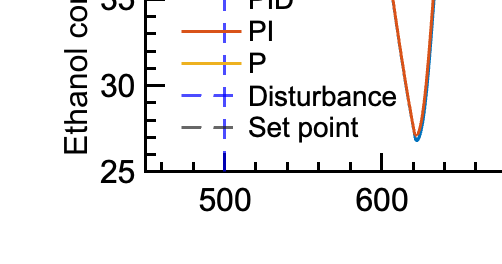

exportgraphics(gcf,"figures/Feedback_WithDisturbance_Dilution_Ethanol.pdf") 
hold off

for ii = 1:1:3 % PID, PI, P
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

% -----
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");
% -----

set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(ii));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(ii));
simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_biotemp)
hold on
end

% xline(500,"--","Disturbance")
% yline(31.5,"--","Set point")
% legend("PID","PI","P","Location","Best")

xline(500,"--b")
yline(31.5,"--")
legend("PID","PI","P","Disturbance","Set point","Location","Best")

xlim([450,1000])

title("")
ylabel("Bioreactor temperature / °C")
xlabel("Time / h")

Plot();

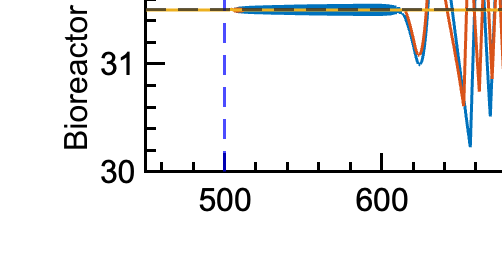

exportgraphics(gcf,"figures/Feedback_WithDisturbance_Dilution_BioTemperature.pdf") 
hold off

for ii = 1:1:3 % PID, PI, P
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

% -----
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "0");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0.5");
% -----

set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(ii));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(ii));
simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_biotemp)
hold on
end

% xline(500,"--","Disturbance")
% yline(31.5,"--","Set point")
% legend("PID","PI","P","Location","Best")

xline(500,"--b")
yline(31.5,"--")
legend("PID","PI","P","Disturbance","Set point","Location","Best")

xlim([500,500.1])

title("")
ylabel("Bioreactor temperature / °C")
xlabel("Time / h")

Plot();

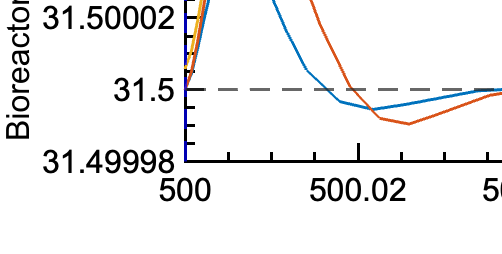

exportgraphics(gcf,"figures/Feedback_WithDisturbance_CoolantTemperature_BioTemperature.pdf") 
hold off

for ii = 1:1:3 % PID, PI, P
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

% -----
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "0");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0.5");
% -----

set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(ii));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(ii));
simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on
end

% xline(500,"--","Disturbance")
% yline(40,"--","Set point")
% legend("PID","PI","P","Location","Best")

xline(500,"--b")
yline(40,"--")
legend("PID","PI","P","Disturbance","Set point","Location","Best")

xlim([500,500.1])

title("")
ylabel("Ethanol concentration / gL^{-1}")
xlabel("Time / h")

Plot();

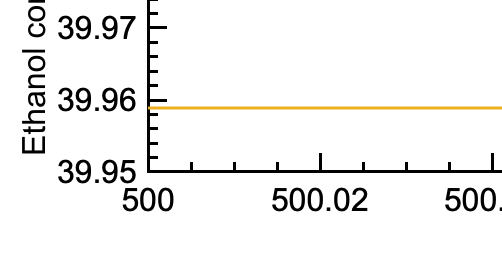

exportgraphics(gcf,"figures/Feedback_WithDisturbance_CoolantTemperature_Ethanol.pdf") 
hold off